% Author: Samin Rajabi
% Created: 2020
% This code involves optimizing portfolios for three types 
% of investors using four asset classes, considering specific 
% risk-return parameters. First, determine strategic allocations without constraints, 
% then explore tactical allocations with flexibility based on a potential outperformance view. 

ret3 = [0.1000 0.0600 0.1000];
vcv3 = [0.0400 0.0040 0.0264; 0.0040 0.0100 0.0044;0.0264 0.0044 0.0484]

vcv3 =     0.0400    0.0040    0.0264
    0.0040    0.0100    0.0044
    0.0264    0.0044    0.0484


 
% 4 Assets with Risk free
ret4 = [ 0.10 0.06 0.10 0.04];
vcv4 = [0.0400 0.0040 0.0264 0; 0.0040 0.0100 0.0044 0 ;0.0264 0.0044 0.0484 0; 0 0 0 0]

vcv4 =     0.0400    0.0040    0.0264         0
    0.0040    0.0100    0.0044         0
    0.0264    0.0044    0.0484         0
         0         0         0         0


 
RisklessRate = 0.04;
BorrowRate = 0.06;
RiskAversion = 3;
 
lb = -1;
ub = 2;
p1 = Portfolio('AssetMean',ret3, 'AssetCovar',vcv3,'RiskFreeRate',RisklessRate,'Budget',1,'LowerBound',lb,'UpperBound',ub)

p1 =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 0.0400
        AssetMean: [3×1 double]
       AssetCovar: [3×3 double]
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 3
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [3×1 double]
       UpperBound: [3×1 double]
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


%%
%Optimize wgt
w1 = estimateMaxSharpeRatio(p1)

w1 =     0.3366
    0.4638
    0.1996


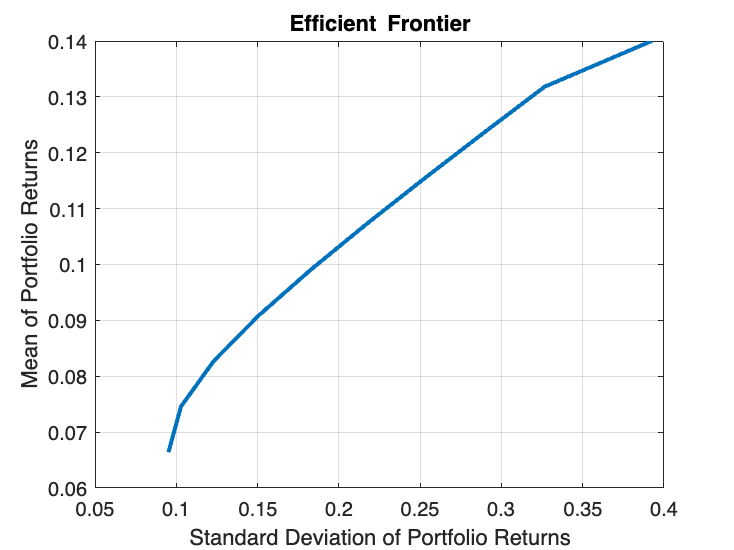

p1risk =     0.0952
    0.1029
    0.1231
    0.1510
    0.1829
    0.2172
    0.2529
    0.2895
    0.3266
    0.3924


p1ret =     0.0664
    0.0746
    0.0828
    0.0909
    0.0991
    0.1073
    0.1155
    0.1236
    0.1318
    0.1400


[p1risk p1ret] = p1.plotFrontier(10)

% [p1risk, p1ret] = estimatePortMoments(p1,w1)
[pwgt] = p1.estimateFrontier(10)

pwgt =     0.1084    0.2324    0.3565    0.4805    0.6045    0.7286    0.8526    0.9766    1.1007    2.0000
    0.8399    0.6355    0.4310    0.2266    0.0222   -0.1823   -0.3867   -0.5911   -0.7956   -1.0000
    0.0517    0.1321    0.2125    0.2929    0.3733    0.4537    0.5341    0.6145    0.6949         0


%%
% finding max u with different A : 1,3 and 6
p1var = times(p1risk,p1risk);
for A = [1 3 6]
    u = p1ret - .5 * A * p1var
   max(u)
end

u =     0.0619
    0.0693
    0.0752
    0.0795
    0.0824
    0.0837
    0.0835
    0.0817
    0.0785
    0.0630


ans = 0.0837

u =     0.0528
    0.0587
    0.0600
    0.0568
    0.0489
    0.0365
    0.0195
   -0.0020
   -0.0282
   -0.0910


ans = 0.0600

u =     0.0392
    0.0428
    0.0373
    0.0226
   -0.0013
   -0.0343
   -0.0764
   -0.1277
   -0.1882
   -0.3220


ans = 0.0428

 
%%
% port allocation
% Average investor
[RiskyRisk, RiskyReturn, RiskyWts, RiskyFraction, OverallRisk, OverallReturn] = portalloc(p1risk, p1ret, pwgt', RisklessRate, BorrowRate, RiskAversion)

RiskyRisk = 0.1193

RiskyReturn = 0.0814

RiskyWts =     0.3366    0.4638    0.1996


RiskyFraction = 0.9714

OverallRisk = 0.1158

OverallReturn = 0.0803

%RiskyRisk =
  %  0.1193
%RiskyReturn =
    %0.0814
%RiskyWts =
   % 0.3366    0.4638    0.1996
%OverallReturn =
    %0.0803
    %%
    % Define Portfolio with Risk free Asset 
   
  p2 = Portfolio('AssetMean',ret4, 'AssetCovar',vcv4,'RiskFreeRate',RisklessRate,'Budget',1,'LowerBound',lb,'UpperBound',ub)

p2 =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 0.0400
        AssetMean: [4×1 double]
       AssetCovar: [4×4 double]
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 4
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [4×1 double]
       UpperBound: [4×1 double]
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


  % Find the weight in efficient frontier eith rf
    [pwgtT] = p2.estimateFrontierByReturn(0.0803)

pwgtT =     0.3272
    0.4510
    0.1941
    0.0277


    %Weight Average Inversors 
    %pwgtT = 
   % %TSX      0.3272
   % % F/TM .  0.4510
   % % SP5     0.1941
   % %rf .     0.0277
    %%
    %Finding for Risk Aversion 6 (conservative)
    RiskAversion6 = 6

RiskAversion6 = 6

    [RiskyRisk, RiskyReturn, RiskyWts, RiskyFraction, OverallRisk, OverallReturn] = portalloc(p1risk, p1ret, pwgt', RisklessRate, BorrowRate, RiskAversion6)

RiskyRisk = 0.1193

RiskyReturn = 0.0814

RiskyWts =     0.3366    0.4638    0.1996


RiskyFraction = 0.4857

OverallRisk = 0.0579

OverallReturn = 0.0601

    %OverallReturn =
    %0.0601
[pwgtT] = p2.estimateFrontierByReturn(0.0601)

pwgtT =     0.1632
    0.2249
    0.0968
    0.5151


% pwgtT =
    %0.1632
   % 0.2249
   % 0.0968
   % 0.5151
   %%
   % 'Very Aggresive 
    RiskAversion1 = 1

RiskAversion1 = 1

     [RiskyRisk, RiskyReturn, RiskyWts, RiskyFraction, OverallRisk, OverallReturn] = portalloc(p1risk, p1ret, pwgt', RisklessRate, BorrowRate, RiskAversion1)

RiskyRisk = 0.2309

RiskyReturn = 0.1105

RiskyWts =     0.7769   -0.2619    0.4850


RiskyFraction = 1

OverallRisk = 0.2309

OverallReturn = 0.1105

    %OverallReturn =
    % 0.1105
     [pwgtT] = p2.estimateFrontierByReturn(0.1105)

pwgtT =     0.5725
    0.7889
    0.3396
   -0.7009


%pwgtT =
  %  0.5725 TSX
  %  0.7889 F/TMX
  %  0.3396 SP5
 %  -0.7009 rf
     
 %%
 %%
 % Part 2
 % Set the bounds as Average investors weight can vary +/- 20%
 lb4 = [0.2618 0.3608 0.1553 0.0221] ;
ub4 = [0.3926 0.5412 0.2329 0.0332];
 
 % Increase return on TSX by 5% 
 retPort4 = [0.15 0.06 0.10 0.04]

retPort4 =     0.1500    0.0600    0.1000    0.0400


%vcv is the same 
 p4 = Portfolio('AssetMean',retPort4, 'AssetCovar',vcv4,'RiskFreeRate',RisklessRate,'Budget',1,'LowerBound',lb4,'UpperBound',ub4)

p4 =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 0.0400
        AssetMean: [4×1 double]
       AssetCovar: [4×4 double]
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 4
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [4×1 double]
       UpperBound: [4×1 double]
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


[pwgtPort4] = p4.estimateFrontierByReturn(0.0803)

pwgtPort4 =     0.2691
    0.5412
    0.1565
    0.0332


 %% 
  % Increase return on TSX by 2.5% 
  retPort5 = [0.125 0.06 0.10 0.04]

retPort5 =     0.1250    0.0600    0.1000    0.0400


   p5 = Portfolio('AssetMean',retPort5, 'AssetCovar',vcv4,'RiskFreeRate',RisklessRate,'Budget',1,'LowerBound',lb4,'UpperBound',ub4)

p5 =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 0.0400
        AssetMean: [4×1 double]
       AssetCovar: [4×4 double]
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 4
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [4×1 double]
       UpperBound: [4×1 double]
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


[pwgtPort5] = p5.estimateFrontierByReturn(0.0803)

pwgtPort5 =     0.2691
    0.5412
    0.1565
    0.0332


% Increase return on TSX by 1%
retPort6 = [0.11 0.06 0.10 0.04]

retPort6 =     0.1100    0.0600    0.1000    0.0400


 p6 = Portfolio('AssetMean',retPort6, 'AssetCovar',vcv4,'RiskFreeRate',RisklessRate,'Budget',1,'LowerBound',lb4,'UpperBound',ub4)

p6 =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 0.0400
        AssetMean: [4×1 double]
       AssetCovar: [4×4 double]
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 4
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [4×1 double]
       UpperBound: [4×1 double]
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


[pwgtPort6] = p6.estimateFrontierByReturn(0.0803)

pwgtPort6 =     0.2950
    0.5165
    0.1553
    0.0332


% Increase return on TSX by 1.1125%
retPort7 = [0.11250 0.06 0.10 0.04]

retPort7 =     0.1125    0.0600    0.1000    0.0400


 p7 = Portfolio('AssetMean',retPort7, 'AssetCovar',vcv4,'RiskFreeRate',RisklessRate,'Budget',1,'LowerBound',lb4,'UpperBound',ub4)

p7 =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 0.0400
        AssetMean: [4×1 double]
       AssetCovar: [4×4 double]
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 4
        AssetList: []
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [4×1 double]
       UpperBound: [4×1 double]
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


[pwgtPort7] = p7.estimateFrontierByReturn(0.0803)

pwgtPort7 =     0.2810
    0.5305
    0.1553
    0.0332
